% Clear the workspace
clear
addpath('./functions/');

%  Load an image
filepath = "images\starfish_noise10.jpg";
disp(filepath)

images\starfish_noise10.jpg


oIm = imread(filepath);
imshow(oIm);
[h,w,chs] = size(oIm)

h = 362

w = 438

chs = 3

imArea = numel(oIm(:,:,1))

imArea = 158556

imArea20Percent = imArea * 0.2

imArea20Percent = 3.1711e+04

maxBlobSize = imArea * 0.025%0.015

maxBlobSize = 3.9639e+03

minBlobSize = imArea * 0.0015%0.006

minBlobSize = 237.8340

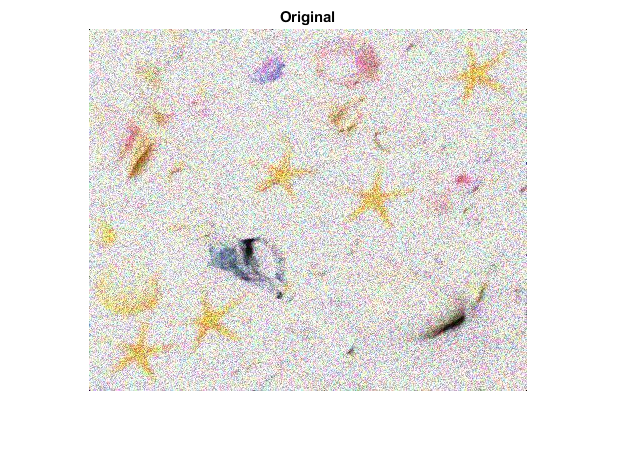

title("Original");

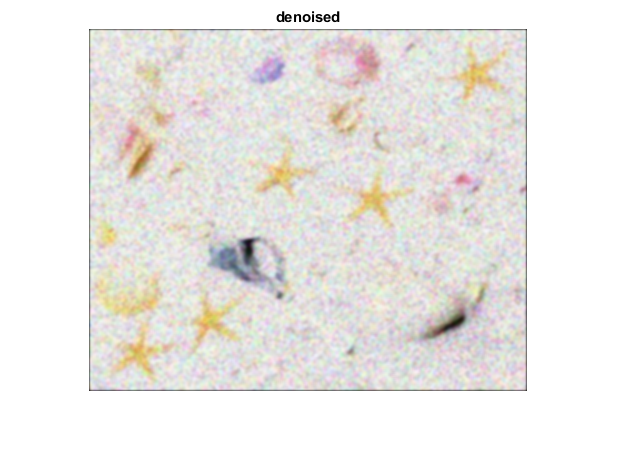


% Orientate landscape.
[h,w,d] = size(oIm);
if (h > w)
    oIm = rot90(oIm);
    oIm = rot90(oIm);
    oIm = rot90(oIm);
end

% % Denoise and enhance.
im = oIm;
[c1,c2,c3] = imsplit(im);
c1 = medfilt2(c1);
c2 = medfilt2(c2);
c3 = medfilt2(c3);
im = cat(3, c1,c2,c3);
im = MeanFilter(im, 3);
% im = DenoiseIsolated(im, "medianfilter");
im = Denoise1(im);

imshow(im);
title("denoised");

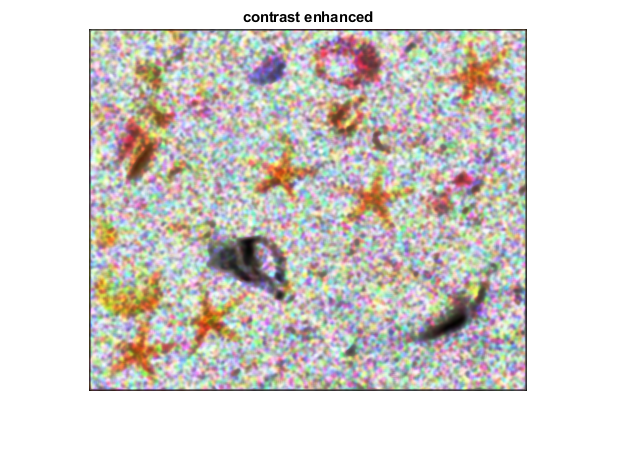


if(IsLowContrast(im))
    % Enhance the contrast of cluttered and low-contrast images.
    [c1,c2,c3] = imsplit(im);
    c1 = adapthisteq(c1);
    c2 = adapthisteq(c2);
    c3 = adapthisteq(c3);
    im = cat(3, c1,c2,c3);
    imshow(im);
    title("contrast enhanced");
end


% Threshold the image in hsv and get a rough mask with candidate blobs.
% mask = logical(HSVInvertedThresh(im));
mask = logical(ThresholdRGB(im));

rMean = 183.5870

rStd = 38.1200

gMean = 176.7237

gStd = 44.9959

bMean = 169.4824

bStd = 50.0561

bVal = 134.9437

didn't use red thresh


channel1Min = 0

channel1Max = 255

channel2Min = 0

channel2Max = 255

channel3Min = 0

channel3Max = 134.9437

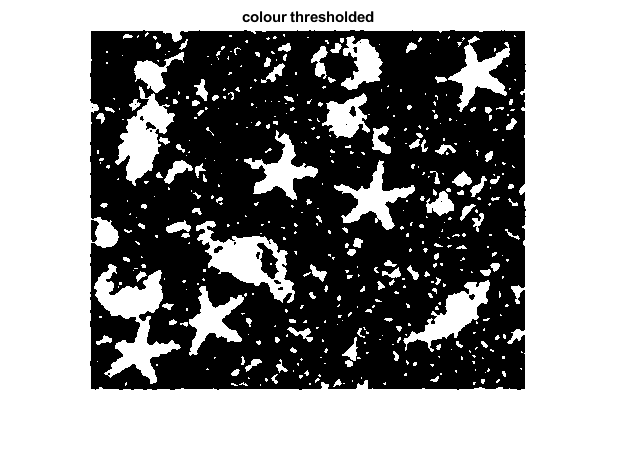

imshow(mask);
title("colour thresholded");

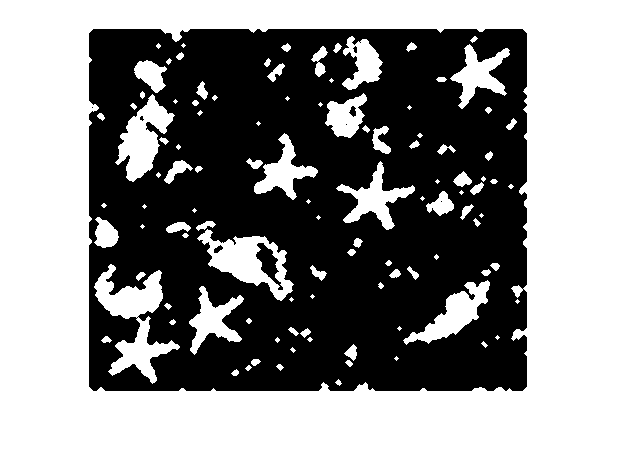


% If the image is primarily dark, invert the mask to make objects the
% foreground.
% if (IsDark(im))
%     mask = ~mask;
% end

% CONDITIONALLY MORPH BASED ON NOISE VALUE
% se = strel('line', 2, 0);
% mask = imerode(mask, se);
% imshow(mask);
% title("erode")

% % Remove large blobs (preserve small "noise" in case they are fragments)
% properties_table = regionprops('table', mask, 'all');
% areas = properties_table.Area;
% minBlobArea = min(areas)
% maxBlobArea = max(areas)
% medianBlobArea = mean2(areas)
% stdBlobArea = std2(areas)
% if ((stdBlobArea * 1.5) > maxBlobSize)
%     maxBlobSize = maxBlobArea;
% end
% mask = bwareafilt(mask, [0 maxBlobSize]);
% imshow(mask);
% title("bwareafilt initial");
% 
% mask = imfill(mask, 'holes');
% imshow(mask);
% title("holes filled");

% % Morph
se = strel('disk', 2);
mask = imopen(mask, se);
imshow(mask);

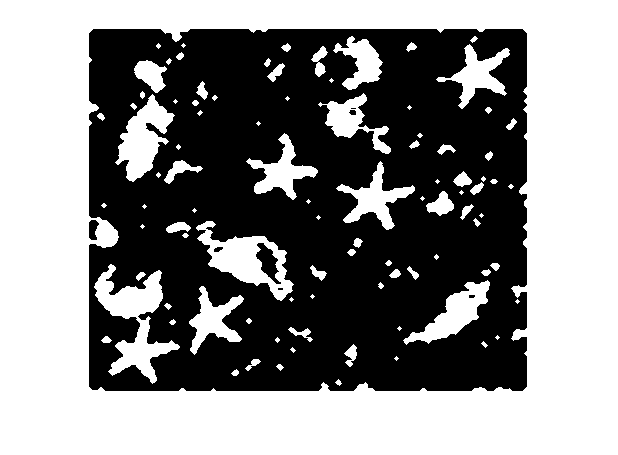

se = strel('line', 4, 0);
mask = imclose(mask, se);
imshow(mask);

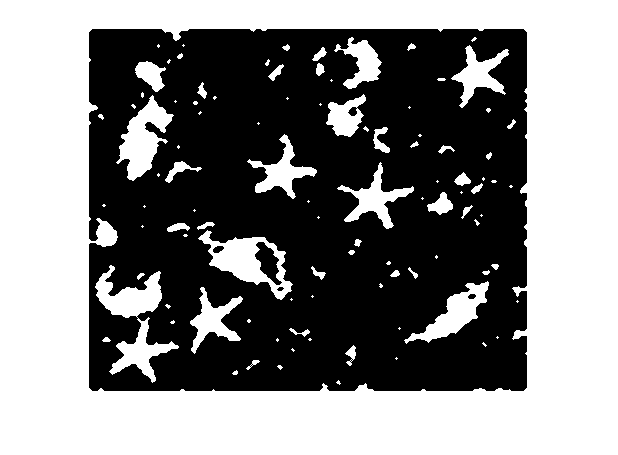

se = strel('diamond', 1);
mask = imerode(mask, se);
se = strel('line', 4, 45);
mask = imclose(mask, se);
imshow(mask);

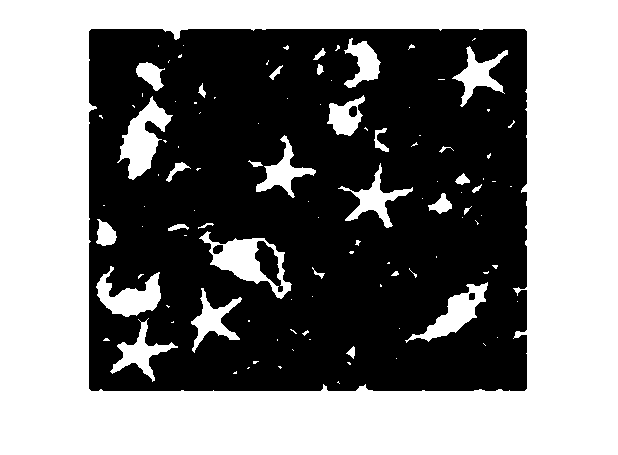

se = strel('diamond', 1);
mask = imerode(mask, se);
se = strel('line', 4, 90);
mask = imclose(mask, se);
imshow(mask);

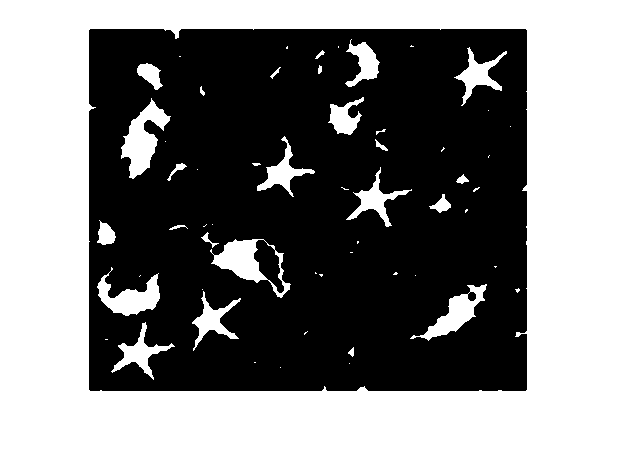

se = strel('diamond', 1);
mask = imerode(mask, se);
se = strel('line', 4, 135);
mask = imclose(mask, se);
imshow(mask);

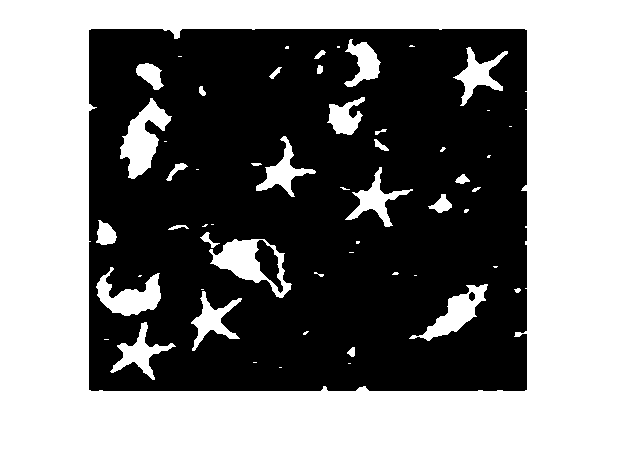


se = strel('line', 3, 0);
mask = imdilate(mask, se);
imshow(mask);

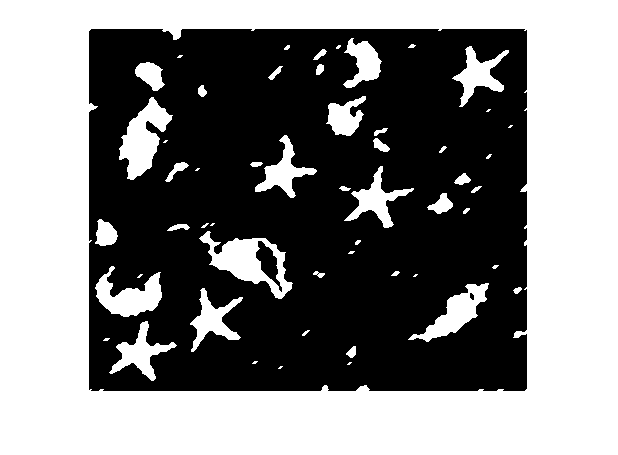

se = strel('diamond', 1);
mask = imclose(mask, se);
se = strel('line', 3, 45);
mask = imdilate(mask, se);
imshow(mask);

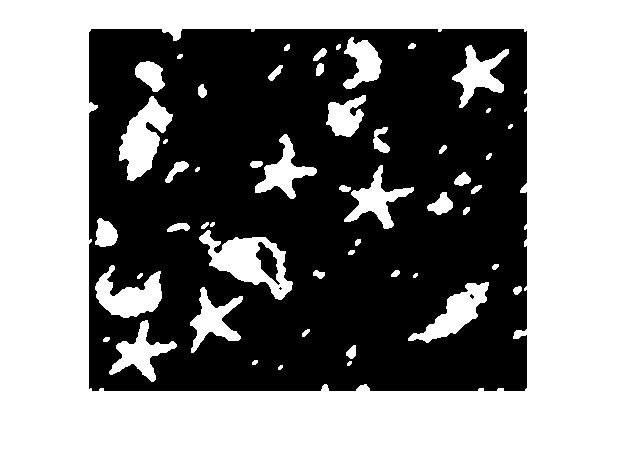

se = strel('diamond', 1);
mask = imclose(mask, se);
se = strel('line', 3, 90);
mask = imdilate(mask, se);
imshow(mask);

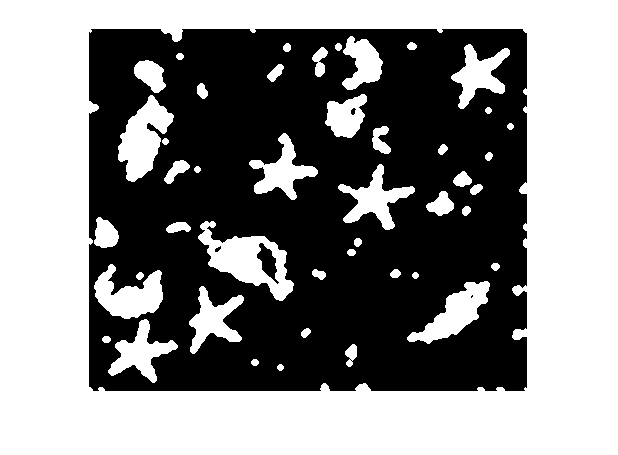

se = strel('diamond', 1);
mask = imclose(mask, se);
se = strel('line', 3, 135);
mask = imdilate(mask, se);
imshow(mask);

% se = strel('diamond', 1);
% mask = imclose(mask, se);


% % Remove large blobs (preserve small "noise" in case they are fragments)
% properties_table = regionprops('table', mask, 'all');
% areas = properties_table.Area;
% minBlobArea = min(areas)
% maxBlobArea = max(areas)
% medianBlobArea = mean2(areas)
% stdBlobArea = std2(areas)
% if ((stdBlobArea * 1.5) > maxBlobSize)
%     maxBlobSize = maxBlobArea;
% end
% mask = bwareafilt(mask, [0 maxBlobSize]);
% imshow(mask);
% title("bwareafilt initial");


% Remove noise
% finalMask = bwareafilt(mask, [minBlobSize maxBlobSize]);
% imshow(finalMask);
% title("bwareafilt denoise")
% If we removed all items, reduce small threshold until objects found or
% % max attempts tried.
% finalMask = mask;
% [~, nCC] = bwlabel(finalMask);
% attempts = 0;
% maxAttempts = 5;
% while (nCC == 0 && attempts < maxAttempts)
%     attempts = attempts + 1
%     minBlobSize = imArea * (0.0015 * attempts)
%     finalMask = bwareafilt(mask, [minBlobSize maxBlobSize]);
%     imshow(finalMask);
%     title("bwareafilt denoise")
%     [~, nCC] = bwlabel(finalMask);
% end

finalMask = mask;
maskall = MSERIsolateStarfish(finalMask);

ans = 5×2 single matrix
  390.4480   46.2710
  286.7236  171.1780
  193.8404  142.7243
  125.0351  291.8458
   52.1524  324.7213


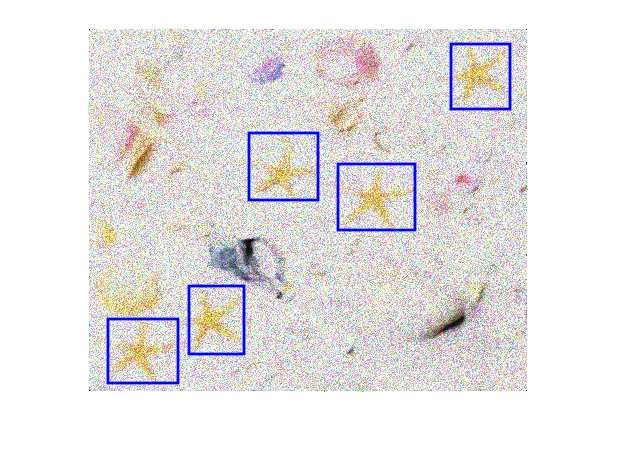


% DRAW FINAL ROIS
DrawROIs(oIm, maskall);


[~, n] = bwlabel(maskall)

n = 5

function diffMask = GetDiffMask(im, imP)
% Get mask of "isolated" noise.
imLnStd = log(std2(im))^2;
diff = abs(double(im) - double(imP));
diffMask = (diff > imLnStd);
end
% % % %

function [imP, noiseValue] = DenoiseIsolated(im, method)
maxPasses = 10;
changeThresh = 50;
dims = ndims(im);
repeat = true;
attempt = 0;


while (repeat && attempt < 3)
    attempt = attempt + 1; % try median and then try mean
    noiseValue = 100; % Reset
    passes = 0; % Reset
    repeat = false;
    imP = im;
    
    if (dims == 2)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated2D(imP, method);
            passes = passes + 1;
        end
    elseif (dims == 3)
        while(noiseValue > changeThresh && passes < maxPasses) % Repeat until change noise value is < thresh.
            [imP, noiseValue] = DenoiseIsolated3D(imP, method);
            passes = passes + 1;
        end
    else
        error("Unsupported number of dimensions. Expected a 2D or 3D array.");
    end
    
    % Outputs in the range of 20-40 are resultant of noisy images benfitting from non-median filter techniques.
    %     if (noiseValue > 30)
    %         disp("Switching mode");
    %         method = "meanfilter";
    %         repeat = true;
    %     end
    % else finish.
end

disp("Method used: " + method);

%     imP = imsharpen(imP, 'amount', 2);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated3D(im, method)
% Separate image channels.
[ch1, ch2, ch3] = imsplit(im);

% Denoise channels individually.
[dnCh1,noiseValue1] = DenoiseIsolated2D(ch1, method);
[dnCh2,noiseValue2] = DenoiseIsolated2D(ch2, method);
[dnCh3,noiseValue3] = DenoiseIsolated2D(ch3, method);

% Concatenate channels to create noise free image.
imP = cat(3, dnCh1, dnCh2, dnCh3);
noiseValue = mean([noiseValue1,noiseValue2,noiseValue3]);
end
% % % %


function [imP, noiseValue] = DenoiseIsolated2D(im, method)
% if s&p or isolated noise
if (method == "medianfilter")
    filtered = medfilt2(im, [5 5]); % [5 5] loses texture but keeps shape. [3 3] keeps texture but more noise.
elseif (method == "meanfilter")
    filtered = conv2(im, ones(3)/9, 'same');
end

diffMask = GetDiffMask(im, filtered);

% Swap noisy pixels for filtered ones
noise = (diffMask == 1);
imP = im;
imP(noise) = filtered(noise);

diffMask = GetDiffMask(im, imP);
noiseValue = GetRelPercentageNoise(im, diffMask);
imshow(diffMask)
title("Other noise value: " + round(noiseValue,2))
end
% % % %


% function bool = IsLowContrast(im)
% % Low range or mean is > 200 || < 50 ;
% RANGE = 75;
% LOW = 40;
% HIGH = 215;
% 
% theMin = min(im(:));
% theMax = max(im(:));
% theRange = theMax - theMin;
% theMean = mean(im(:));
% theStd = std2(im(:));
% theMeanPStd = theMean + theStd;
% theMeanMStd = theMean - theStd;
% theRange2 = theMeanPStd - theMeanMStd;
% 
% bool = 0;
% if (theRange2 < RANGE || (theMeanMStd < LOW|| theMeanPStd > HIGH))
%     bool = 1;
%     disp("LOW CONTRAST");
% end
% end


% function stats = OverlayRois(imP, c, t, circle)
% CC = bwconncomp(imP); % get "connected components" in the binary mask
% % Uncomment to colour each segment randomly
% % L = labelmatrix(CC);
% % RGB = label2rgb(L,'cool','k','shuffle');
% % imshow(RGB)
% 
% % Collate ALL region properties of each connect component (region)
% stats = regionprops("table",CC,"all");
% 
% % DRAW BOUNDING BOXES AND GET BLOB COUNT
% disp(CC.NumObjects + " objects detected") % Output text
% info = regionprops(CC,'Boundingbox') ; % Get region info from region properties
% 
% % Draw bounding boxes for each region/connected component detected
% for k = 1 : length(info)
%     BB = info(k).BoundingBox; % get bounding box measures for region 'k'
%     if circle == 'n'
%         rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor',c,'LineWidth',t); % Draw roi as rectangle with colour c and line thickness t.
%     else
%         rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor',c,'LineWidth',t,"Curvature",[1,1]) ; % Draw roi as circle "
%     end
% end
% end
% % Simple facade for drawing rois on original image. c = colour of region
% % outline, t = thickness, circle = 'y' or 'n' for circle or rect rois.
% function stats = DrawRois(original, processed, c, t,circle)
% figure
% imshow(original)
% stats = OverlayRois(processed, c, t, circle);
% end


function t = statxture(f, scale)
%STATXTURE Computes statistical measures of texture in an image.
%   T = STATXURE(F, SCALE) computes six measures of texture from an
%   image (region) F. Parameter SCALE is a 6-dim row vector whose
%   elements multiply the 6 corresponding elements of T for scaling
%   purposes. If SCALE is not provided it defaults to all 1s.  The
%   output T is 6-by-1 vector with the following elements:
%     T(1) = Average gray level
%     T(2) = Average contrast
%     T(3) = Measure of smoothness
%     T(4) = Third moment
%     T(5) = Measure of uniformity
%     T(6) = Entropy

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.5 $  $Date: 2004/11/04 22:33:43 $

if nargin == 1
    scale(1:6) = 1;
else % Make sure it's a row vector.
    scale = scale(:)';
end

% Obtain histogram and normalize it.
p = imhist(f);
p = p./numel(f);
L = length(p);

% Compute the three moments. We need the unnormalized ones
% from function statmoments. These are in vector mu.
[~, mu] = statmoments(p, 3); % Hole for the first variable.

% Compute the six texture measures:
% Average gray level.
t(1) = mu(1);
% Standard deviation.
t(2) = mu(2).^0.5;
% Smoothness.
% First normalize the variance to [0 1] by
% dividing it by (L-1)^2.
varn = mu(2)/(L - 1)^2;
t(3) = 1 - 1/(1 + varn);
% Third moment (normalized by (L - 1)^2 also).
t(4) = mu(3)/(L - 1)^2;
% Uniformity.
t(5) = sum(p.^2);
% Entropy.
t(6) = -sum(p.*(log2(p + eps)));

% Scale the values.
t = t.*scale;
end


function [v, unv] = statmoments(p,  n)
%STATMOMENTS Computes statistical central moments of image histogram.
%   [W, UNV] = STATMOMENTS(P, N) computes up to the Nth statistical
%   central moment of a histogram whose components are in vector
%   P. The length of P must equal 256 or 65536.
%
%   The program outputs a vector V with V(1) = mean, V(2) = variance,
%   V(3) = 3rd moment, . . . V(N) = Nth central moment. The random
%   variable values are normalized to the range [0, 1], so all
%   moments also are in this range.
%
%   The program also outputs a vector UNV containing the same moments
%   as V, but using un-normalized random variable values (e.g., 0 to
%   255 if length(P) = 2^8). For example, if length(P) = 256 and V(1)
%   = 0.5, then UNV(1) would have the value UNV(1) = 127.5 (half of
%   the [0 255] range).

%   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
%   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
%   $Revision: 1.3 $  $Date: 2003/05/24 22:43:02 $

Lp = length(p);
if (Lp ~= 256) && (Lp ~= 65536)
    error('P must be a 256- or 65536-element vector.');
end
G = Lp - 1;

% Make sure the histogram has unit area, and convert it to a
% column vector.
p = p/sum(p); p = p(:);

% Form a vector of all the possible values of the
% random variable.
z = 0:G;

% Now normalize the z's to the range [0, 1].
z = z./G;

% The mean.
m = z*p;

% Center random variables about the mean.
z = z - m;

% Compute the central moments.
v = zeros(1, n);
v(1) = m;
for j = 2:n
    v(j) = (z.^j)*p;
end

if nargout > 1
    % Compute the uncentralized moments.
    unv = zeros(1, n);
    unv(1)=m.*G;
    for j = 2:n
        unv(j) = ((z*G).^j)*p;
    end
end
end


% function [BW,maskedRGBImage] = RGBThresh(RGB)
% %createMask  Threshold RGB image using auto-generated code from colorThresholder app.
% %  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
% %  auto-generated code from the colorThresholder app. The colorspace and
% %  range for each channel of the colorspace were set within the app. The
% %  segmentation mask is returned in BW, and a composite of the mask and
% %  original RGB images is returned in maskedRGBImage.
% 
% % Auto-generated by colorThresholder app on 11-May-2020
% %------------------------------------------------------
% [r,g,b] = imsplit(RGB);
% rMean = mean2(r)
% rStd = std2(r)
% gMean = mean2(g)
% gStd = std2(g)
% bMean = mean2(b)
% bStd = std2(b)
% bLogStd = log(bStd);
% gLogStd = log(gStd);
% 
% bVal = 255;
% gVal = 255;
% bStdMultiplier = round(((bLogStd * 0.1) * (bLogStd * 0.45)),2,'significant');
% gStdMultiplier = bStdMultiplier * 0.5;
% if (min([rMean, bMean, gMean]) == rMean)
%     bStdMultiplier = bStdMultiplier * 2;
% end
% 
% if ((gMean + 5)< bMean && gMean)
%     % Mostly reduce green channel.
%     gVal = max(gMean - (gStd * gStdMultiplier), 0)
%     if (gVal == 0)
%         gVal = gMean + (gStd * gStdMultiplier)
%     elseif (gVal < 25)
%         gVal = gVal * 10
%     end
%     if (bMean >= 195 && bMean <= 235)
%         bVal = bMean
%     end
% else
%     % Mostly reduce blue channel.
%     bVal = max(bMean - (bStd * bStdMultiplier), 0)
%     if (bVal == 0)
%         bVal = gMean + (bStd * gStdMultiplier)
%     elseif (bVal < 25)
%         bVal = bVal * 10
%     end
%     if (gMean >= 195 && gMean <= 235)
%         gVal = gMean
%     end
% end
% 
% rVal = 150;
% if (rMean < 200)
%     rVal = 0;
%     disp("didn't use red thresh");
% end
% 
% % Convert RGB image to chosen color space
% I = RGB;
% 
% % Define thresholds for channel 1 based on histogram settings
% channel1Min = rVal
% channel1Max = 255.000
% 
% % Define thresholds for channel 2 based on histogram settings
% channel2Min = 0.000
% channel2Max = gVal
% 
% % Define thresholds for channel 3 based on histogram settings
% channel3Min = 0.000
% channel3Max = bVal
% 
% % Create mask based on chosen histogram thresholds
% sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
%     (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
%     (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
% BW = sliderBW;
% 
% % Initialize output masked image based on input image.
% maskedRGBImage = RGB;
% 
% % Set background pixels where BW is false to zero.
% maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
% 
% end


% function bool = IsDark(im)
%     grayScaler = 1;
%     if (max(im(:)) <= 1)
%         grayScaler = 255;
%     end
%     
%     imMedian = median(im(:));
%     if (imMedian <= (135 / grayScaler))
%         bool = true;
%         disp("IS DARK");
%     else
%         bool = false;
%     end
% end

function [BW,maskedRGBImage] = HSVInvertedThresh(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 13-May-2020
%------------------------------------------------------

% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.876;
channel1Max = 0.482;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.597;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end

function imP = Denoise(im)
oim = im;
w = [0 1 0; 1 -4 1; 0 1 0]; % 3x3 laplacian

c = 2;
r = 5;
n = 0;

%  Laplacian edge filter
im1 = imfilter(im, w);
imshow(im1)
title("Laplacian edge filtered");
%  Laplacian edge filter CONVOLUTION
im2 = convn(im, w, 'same');
imshow(im2)
title("Laplacian convoluted");
%  DIFFERENCE between edges and convolution
noise = double(im2) - double(im1);
% imshow(noise)
% title("noise (conv - edge)");

% Split noise channels
[n1,n2,n3] = imsplit(noise);
n1 = n1 > 0;
n1NoiseLevel = 1 - (100/sum(n1(:)))
n2 = n2 > 0;
n2NoiseLevel = 1 -(100/sum(n2(:)))
n3 = n3 > 0;
n3NoiseLevel = 1 - (100/sum(n3(:)))

filtered = oim;
[f1,f2,f3] = imsplit(filtered);
f1 = medfilt2(f1);
f2 = medfilt2(f2);
f3 = medfilt2(f3);
filtered = cat(3, f1, f2, f3);
% imshow(filtered);
% title("filtered");


% Denoise channels
[c1d,c2d,c3d] = imsplit(filtered);
c1d(n1) = f1(n1);
% c1d= imfilter(c1d, ones(3)/9, 'same');
c2d(n2) = f2(n2);
% c2d= imfilter(c2d, ones(3)/9, 'same');
c3d(n3) = f3(n3);
% c3d= imfilter(c3d, ones(3)/9, 'same');
denoised = cat(3, c1d,c2d,c3d);
% imshow(denoised);
% title("denoised");

denoised(:,:,1) = adapthisteq(denoised(:,:,1));
denoised(:,:,2) = adapthisteq(denoised(:,:,2));
denoised(:,:,3) = adapthisteq(denoised(:,:,3));
% imshow(denoised);
% title("CE");

imP = denoised;
end


function imP = Denoise1(im)
oim = im;

%  create filtered version
filtered = oim;
[f1,f2,f3] = imsplit(filtered);
f1 = medfilt2(f1);
f2 = medfilt2(f2);
f3 = medfilt2(f3);
filtered = cat(3, f1, f2, f3);

% Get diff between filtered image and original
diffMask = filtered - oim;

% Threshold pixels that are significantly different and assume them to be
% noise.
noiseThresh = 30;
[n1,n2,n3] = imsplit(diffMask);
n1 = n1 > noiseThresh;
n2 = n2 > noiseThresh;
n3 = n3 > noiseThresh;

% Replace noisy pixels with filtered pixels.
[c1,c2,c3] = imsplit(oim);
c1(n1) = f1(n1);
c2(n2) = f2(n2);
c3(n3) = f3(n3);
denoised = cat(3, c1,c2,c3);
imshow(denoised);
title("denoised");

% Apply mean filter for additional smoothing.
[c1,c2,c3] = imsplit(denoised);
c1 = imfilter(c1, ones(3)/9, 'same');
c2 = imfilter(c2, ones(3)/9, 'same');
c3 = imfilter(c3, ones(3)/9, 'same');
denoised = cat(3, c1,c2,c3);
imshow(denoised);
title("denoised");

% denoised = imsharpen(denoised);
% imshow(denoised);
% title("sharpened");


% % Enhance Contrast
% denoised(:,:,1) = adapthisteq(denoised(:,:,1));
% denoised(:,:,2) = adapthisteq(denoised(:,:,2));
% denoised(:,:,3) = adapthisteq(denoised(:,:,3));
% imshow(denoised);
% title("CE");
imP = denoised;
end